# Odometry Noise Analysis

David Olson, 14 Apr 21

**This live script assumes you have run the simulation for the qbot2 moving straight for a long time, othewise the code will return wacky results!**

## View the Noise due to the poor derivative taken

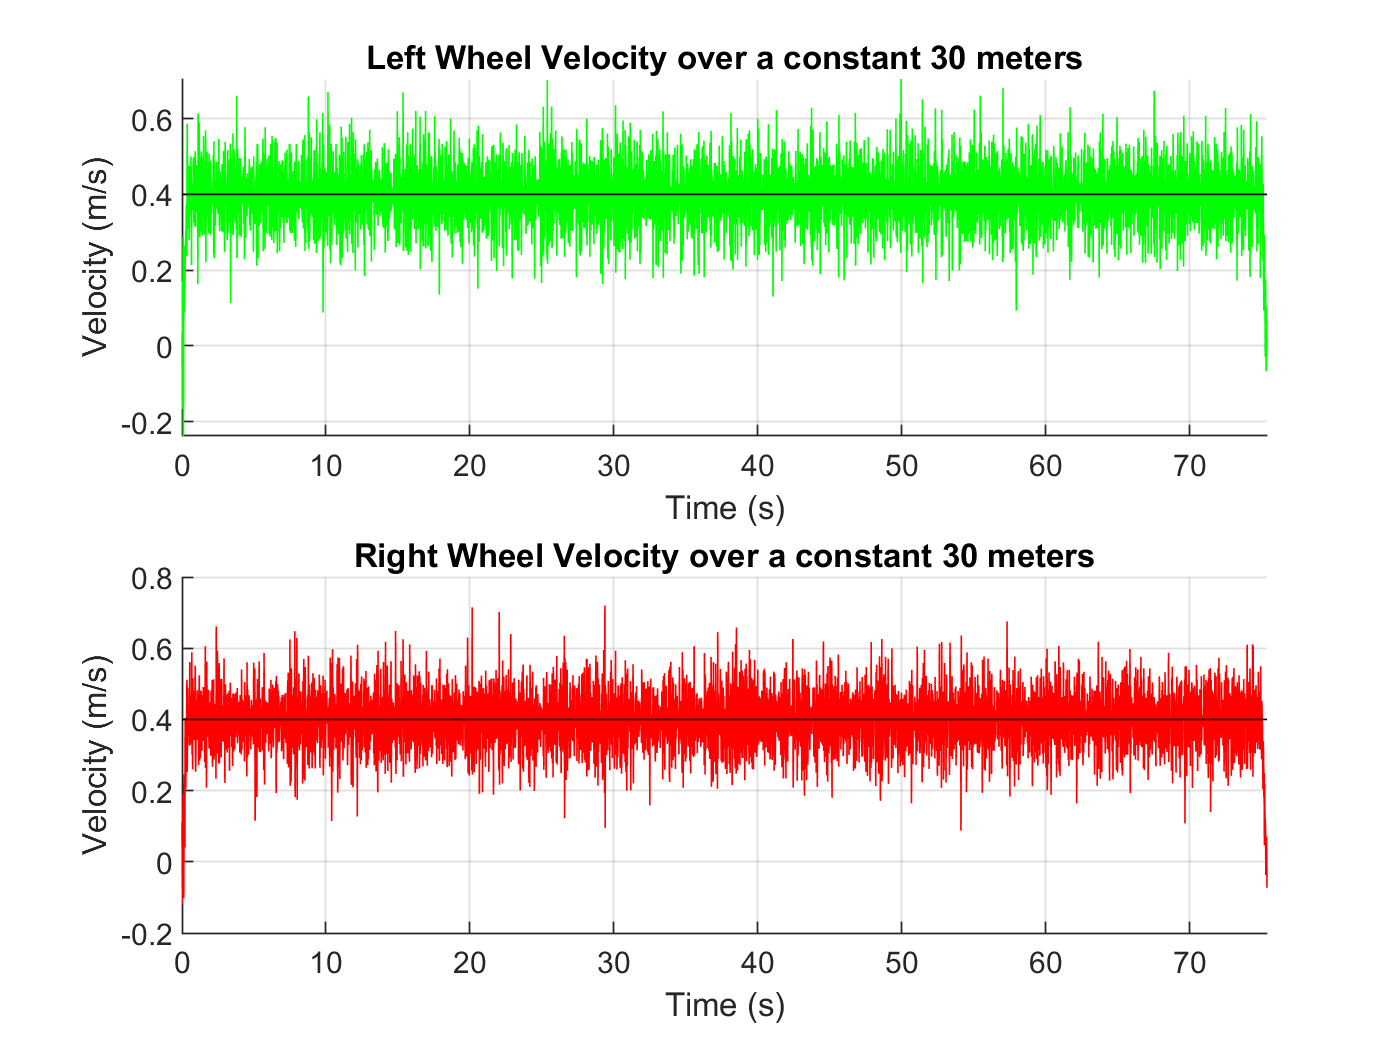

t = out.tout;

v_l = out.v_l.Data;
v_r = out.v_r.Data;

figure
subplot(2,1,1)
hold on
plot(t, v_l, 'g')
line([t(1) t(end)], [0.4 0.4], 'Color', 'k')
title('Left Wheel Velocity over a constant 30 meters')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
xlim([t(1) t(end)])
% ylim([0 0.6])
grid on
subplot(2,1,2)
hold on
plot(t, v_r, 'r')
line([t(1) t(end)], [0.4 0.4], 'Color', 'k')
title('Right Wheel Velocity over a constant 30 meters')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
xlim([t(1) t(end)])
% ylim([0 0.6])
grid on

## Calculate the std of the noise

% Theoretical Noise Expected
sigma_d = P.sigma_odo_d;
dt = P.dt;

sigma_v_wheel = (sqrt(2) * sigma_d) / dt;
disp(sigma_v_wheel)

    0.0866




% Simulation Noise Achieved
v_l_d = detrend(v_l);
v_r_d = detrend(v_r);
disp(std(v_l_d))

    0.0903



disp(std(v_r_d))

    0.0889



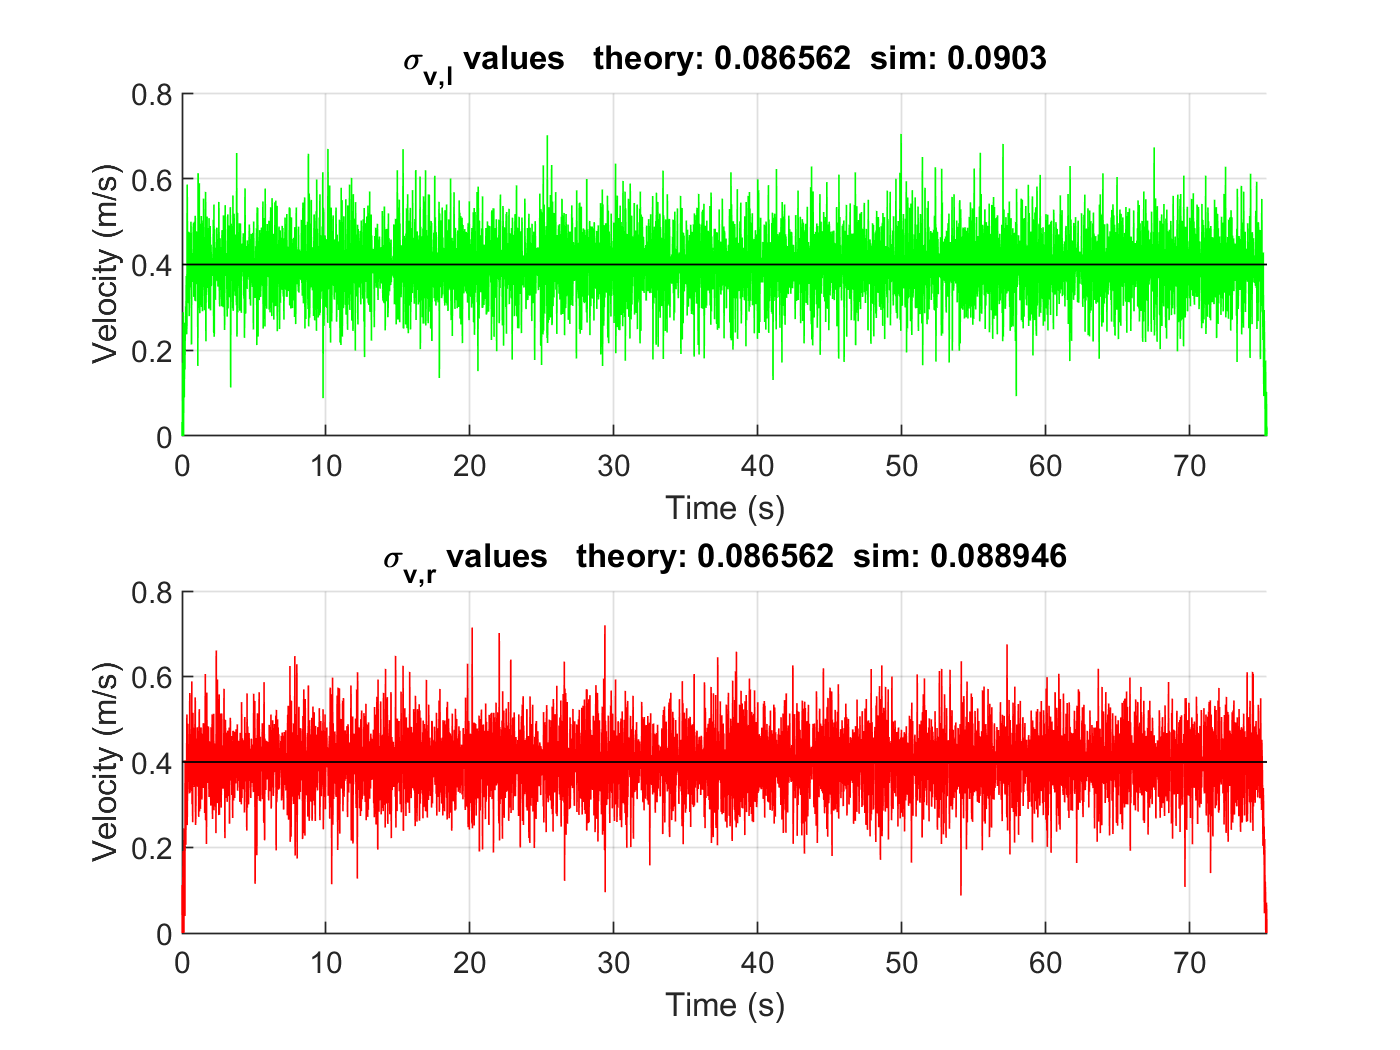


figure
subplot(2,1,1)
hold on
plot(t, v_l, 'g')
line([t(1) t(end)], [0.4 0.4], 'Color', 'k')
str1 = ['theory: ', num2str(sigma_v_wheel), '  sim: ', num2str(std(v_l_d))];
title(['\sigma_v_,_l values   ', str1])
xlabel('Time (s)')
ylabel('Velocity (m/s)')
xlim([t(1) t(end)])
ylim([0 0.8])
grid on
subplot(2,1,2)
hold on
plot(t, v_r, 'r')
line([t(1) t(end)], [0.4 0.4], 'Color', 'k')
str2 = ['theory: ', num2str(sigma_v_wheel), '  sim: ', num2str(std(v_r_d))];
title(['\sigma_v_,_r values   ', str2])
xlabel('Time (s)')
ylabel('Velocity (m/s)')
xlim([t(1) t(end)])
ylim([0 0.8])
grid on

## Confirming Noise in $\sigma_{v_{\mathrm{tb},x}^b }$

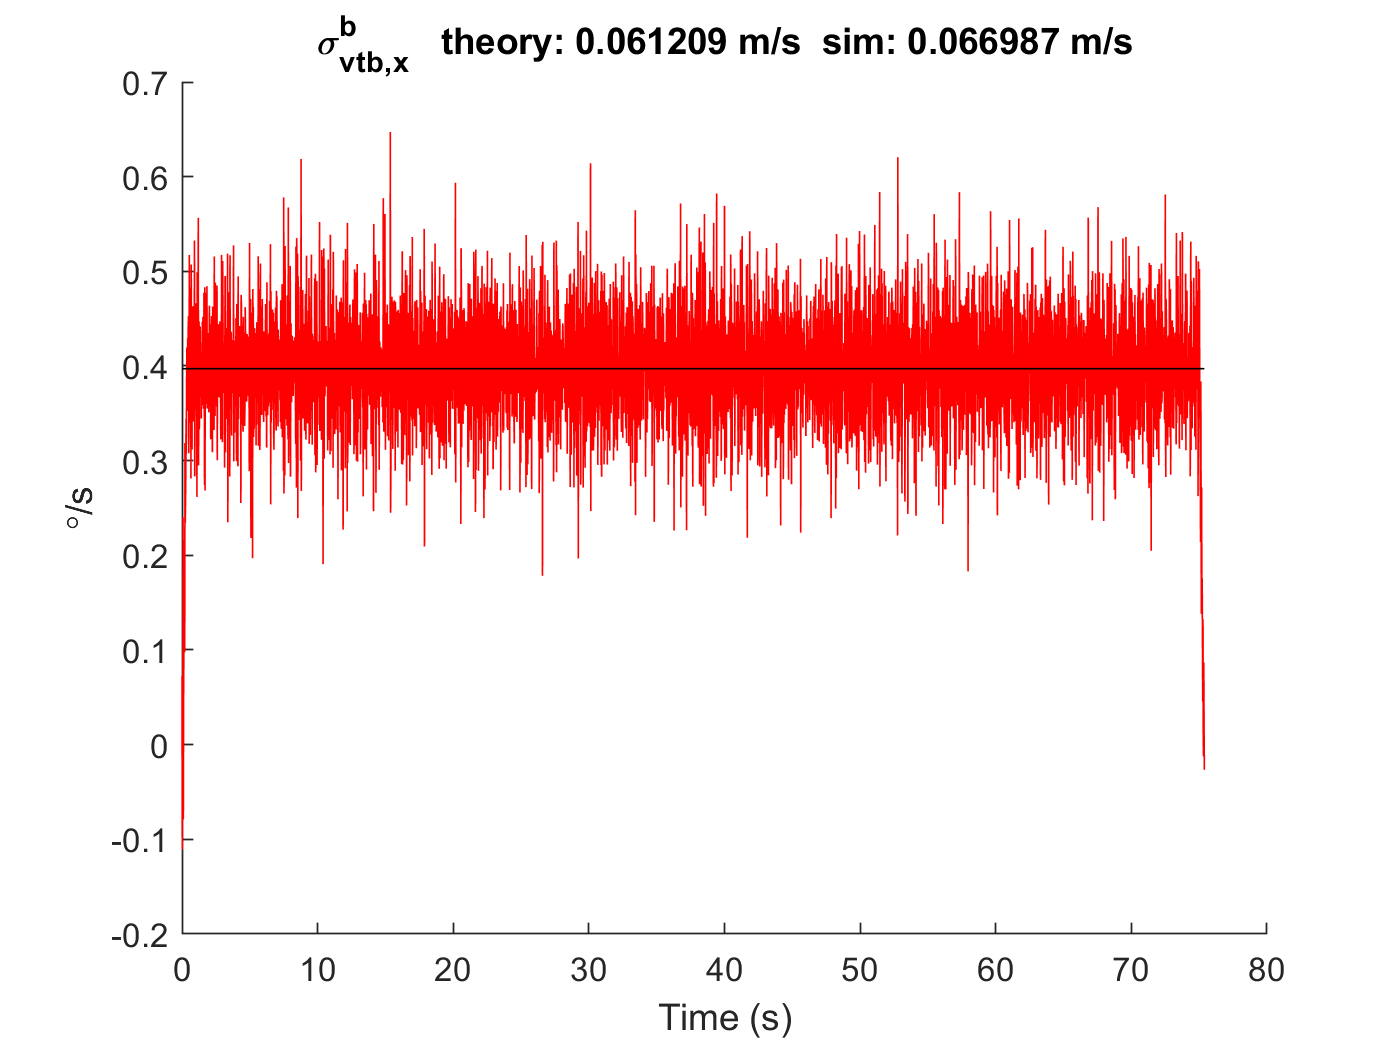

% Theoretical sigma_v_b__t_b_x
sigma_v_x = sigma_v_wheel / sqrt(2);

% Simulated sigma_v_b__t_b_x
for ii = 1 : length(v_l)
    v_x(ii) = (v_l(ii) + v_r(ii)) / 2;
end

v_x_d = detrend(v_x);

figure
hold on
plot(t, v_x, 'r')
line([t(1) t(end)], [mean(v_x) mean(v_x)], 'Color', 'k')
str3 = ['\sigma_v^b_t_b_,_x   theory: ', num2str(sigma_v_x)];
str4 = [' m/s  sim: ', num2str(std(v_x_d)), ' m/s'];
title([str3 str4])
xlabel('Time (s)')
ylabel('\circ/s')
hold off

## Using this section for $\omega {\;}_{z\;}$

% Theoretical
sigma_w_z = (sqrt(2) * sigma_v_wheel) / P.diameter;
disp(sigma_w_z * 180/pi)

   20.0400



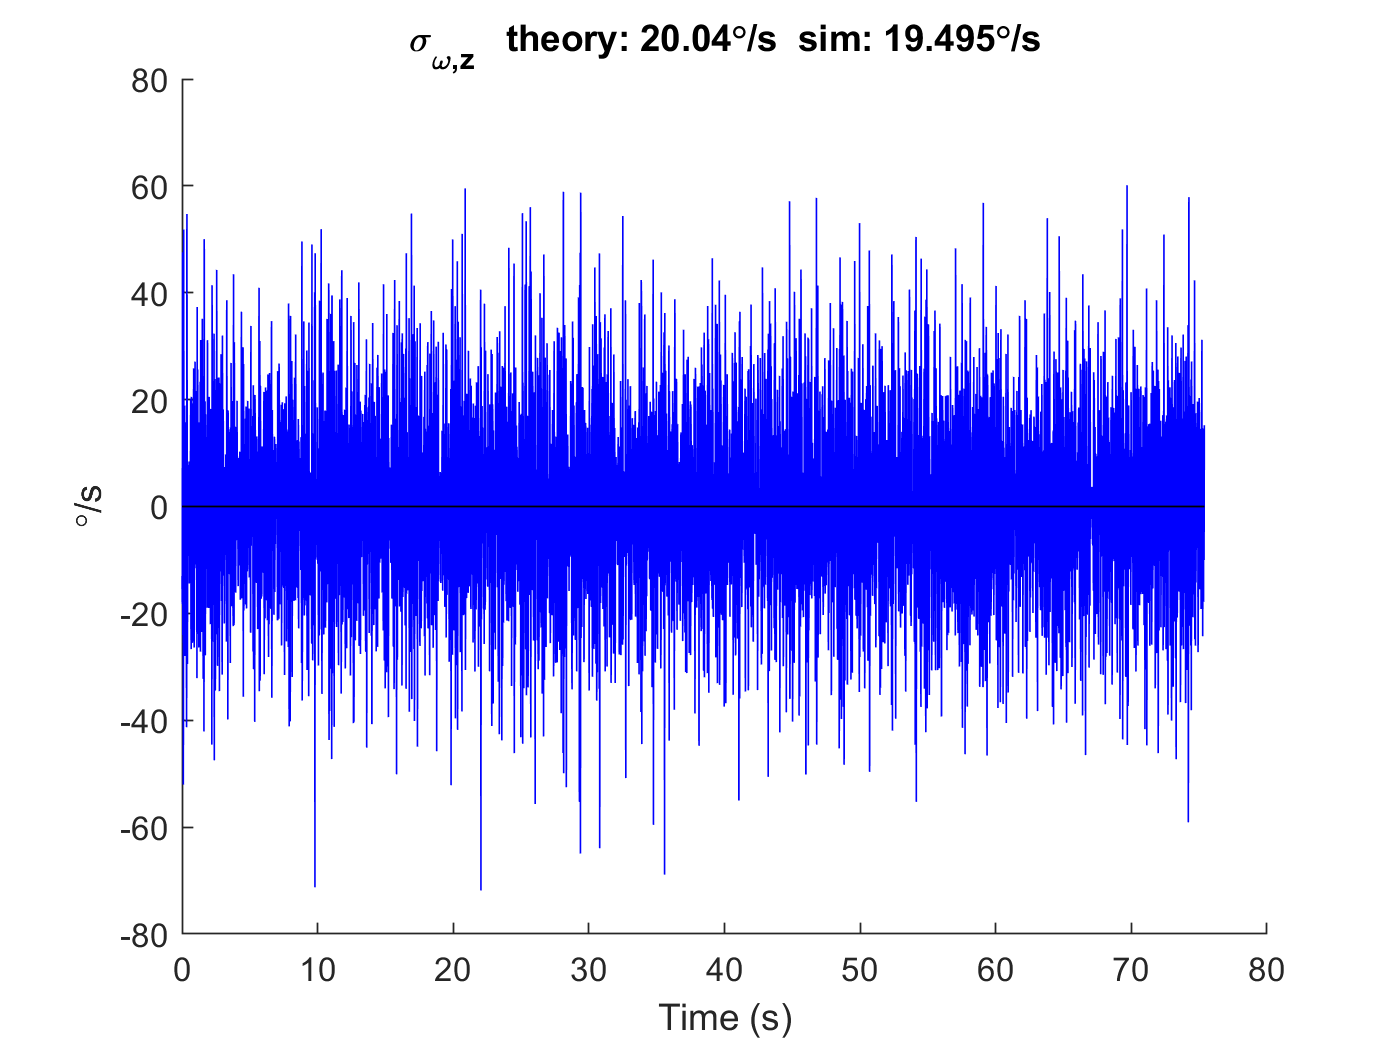


% sigma_w_z = (1.25 * sqrt(2) * sigma_v_wheel) / P.diameter;
% disp(sigma_w_z * 180/pi)

% Simulation
for ii = 1 : length(v_l)
    w_z(ii) = (v_l(ii) - v_r(ii)) / P.diameter;
end

w_z_d = detrend(w_z);

figure
hold on
plot(t, w_z * 180/pi, 'b')
line([t(1) t(end)], 180/pi * [mean(w_z) mean(w_z)], 'Color', 'k')
str3 = ['\sigma_\omega_,_z   theory: ', num2str(sigma_w_z * 180/pi)];
str4 = ['\circ/s  sim: ', num2str(std(w_z_d) * 180/pi), '\circ/s'];
title([str3 str4])
xlabel('Time (s)')
ylabel('\circ/s')
hold off